# COMM.SYS.450 Multicarrier and Multiantenna Techniques

## Exercise 4

Start by defining the system parameters.

number_of_active_subcarriers = 20;
subcarrier_spacing = 15e3;
FFT_size = power(2, ceil(log2(number_of_active_subcarriers)));
QAM_order_data = 16;
QAM_order_pilot = 2;
number_of_frames = 2;
number_of_pilots_per_frame = 1;
number_of_data_per_frame = 3;
frame_length = number_of_pilots_per_frame + number_of_data_per_frame;
Fs = subcarrier_spacing * FFT_size; % sampling frequency

Generate the data streams.

tx_data = randi([0, QAM_order_data-1], number_of_active_subcarriers, ...
    number_of_data_per_frame * number_of_frames);
tx_pilot = randi([0, QAM_order_pilot-1], number_of_active_subcarriers, ...
    number_of_pilots_per_frame * number_of_frames);

#### Transmitter Implementation

Generate the QAM symbols.

tx_data_symbols = qammod(tx_data, QAM_order_data, 'UnitAveragePower', true);
tx_pilot_symbols = qammod(tx_pilot, QAM_order_pilot, 'UnitAveragePower', true);

Create the frame structure. The for loop allows to easily extend beyond two frames.

tx_frame = zeros(number_of_active_subcarriers, frame_length * number_of_frames);
for i = 0:number_of_frames-1
    tx_frame(:,i * frame_length + 1:(i + 1) * frame_length) = [tx_pilot_symbols(:, ...
        i * number_of_pilots_per_frame + 1 : ...
        (i + 1) * number_of_pilots_per_frame) ...
        tx_data_symbols(:, i * number_of_data_per_frame + 1 : ...
        (i + 1) * number_of_data_per_frame)];
end

Zero-pad the unused subcarriers and shift zero-frequency component to center of spectrum.

% zero-padded symbols
zp_length = (FFT_size - number_of_active_subcarriers);
tx_zp_frame = [zeros(zp_length / 2, frame_length * number_of_frames);
              tx_frame;
              zeros(zp_length / 2, frame_length * number_of_frames)];
tx_szp_frame = fftshift(tx_zp_frame, 1); % shifted and zero-padded symbols

Generate the OFDM signal using IFFT.

tx_bb_signal = ifft(tx_szp_frame, FFT_size); % baseband signal

Add the cyclic prefix.

cp_duration = 1/4 * FFT_size;
cp = tx_bb_signal(end-cp_duration+1:end,:);
tx_cp_bb_signal = [cp; tx_bb_signal]; % cyclic-prefixed baseband signal

#### Channel & Receiver Implementation

Transmit over a multipath channel, whereas the channel changes for every frame.

channel_1 = [1, 0.6, 0, 0.1];
channel_2 = [1, 0.8, 0, 0.15];

channel_1_frequency_response = fft(channel_1, FFT_size).';
channel_2_frequency_response = fft(channel_2, FFT_size).';

snr_dB = 40; % signal-to-noise ratio
snr_lin = 10^(snr_dB / 10);

for i = 0:number_of_frames-1
    % Select the filter based on frame number
    if i == 0
        propagation_channel = channel_1;
    else
        propagation_channel = channel_2;
    end
    
    % Pass the whole frame through the same channel
    rx_cp_bb_signal = filter(propagation_channel, 1, ...
        tx_cp_bb_signal(:, i * frame_length + 1: ...
        (i + 1) * frame_length));
    
    % Get matrix dimensions for generating noise
    [m, n] = size(rx_cp_bb_signal);
   
    % Simulate the noise
    noise = 1 / sqrt(2) * (randn(m, n) + 1j * randn(m, n));
    noise = noise / sqrt(snr_lin) * rms(rx_cp_bb_signal, "all");

    % Add the noise
    rx_cp_bb_signal = rx_cp_bb_signal + noise;
    
    % Remove the cyclix prefix
    rx_bb_signal = rx_cp_bb_signal(cp_duration+1:end,:);
    
    % Perform OFDM demodulation
    rx_szp_symbols = fft(rx_bb_signal, FFT_size);
    
    % Remove inactive subcarriers
    rx_zp_symbols = ifftshift(rx_szp_symbols, 1);
    rx_symbols = rx_zp_symbols(1 + zp_length / 2:end - zp_length / 2,:);
    
    % Estimate the channel using only the pilot of the frame
    zf_coefficients = rx_symbols(:, 1) ./ tx_pilot_symbols(:, i + 1);
    
    % Equalize all received symbols using the coefficients
    rx_eq_symbols = rx_symbols ./ zf_coefficients;
    
    % Collect the equalized data symbols for postprocessing later
    rx_eq_symbols_all(:, i * number_of_data_per_frame + 1 : ...
        (i + 1) * number_of_data_per_frame) = rx_eq_symbols(:, 2:end);
    
end

#### Received Signal Analysis

Plot the symbols.

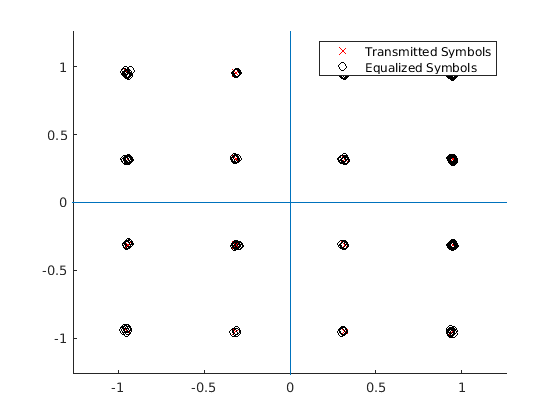

figure
scatter(real(tx_data_symbols(:)), imag(tx_data_symbols(:)), 'rx'), hold on
scatter(real(rx_eq_symbols_all(:)), imag(rx_eq_symbols_all(:)), 'k')
line([0 0], [-0.3162*5 0.3162*5])
line([-0.3162*5 0.3162*5], [0 0])
xlim([-0.3162*4 0.3162*4])
ylim([-0.3162*4 0.3162*4])
legend('Transmitted Symbols','Equalized Symbols')
hold off

Demodulate the symbols.

rx_data = qamdemod(rx_eq_symbols_all, QAM_order_data, 'UnitAveragePower', true);

Check if transmitted and received data are equal.

if isequal(tx_data, rx_data)
    fprintf("Transmitted and received data streams are equal!")
else
    fprintf("Transmitted and received data streams are not equal!")
end

Transmitted and received data streams are equal!